対象物体姿勢thetaによるC-Closure Object同士の重なり領域D_iの変化をプロットしたグラフの作成

file_name = '../../img/sample.png'; % 対象物体となる画像ファイル(png)
c_cls_search_interval = 2.0;
robot_r = 5;

dcc_search_interval = 1*c_cls_search_interval;
robot_corners = 36;
dots_spacing = 1.0;
delta = 10^-8;

addpath('../../func','-end')
addpath('../../class','-end')

エンドエフェクタのとなる円形輪郭となる点群を生成

% make robot's boundary
s_x = round(robot_r*cos(transpose(1:robot_corners)*2*pi/robot_corners),3);
s_y = round(robot_r*sin(transpose(1:robot_corners)*2*pi/robot_corners),3);

C-Closure Objectのアルファシェイプを生成

c_cls = get_C_closure_object2d(file_name,robot_r,robot_corners,dots_spacing,c_cls_search_interval);

        1380



C-Closure Objectの輪郭となる点群を抽出し，

その点群から多角形表現されたC-Closure Objectを生成

object_X = c_cls.XLimits(1,2)-c_cls.XLimits(1,1);
object_Y = c_cls.YLimits(1,2)-c_cls.YLimits(1,1);

c_cls_1_shp = alphaShape(double(c_cls.Location(:,1:2)), c_cls_search_interval/(fix(sqrt(2)*(10^10))/(10^10)),'HoleThreshold',10^12);
[~,c_cls_1_b] = boundaryFacets(c_cls_1_shp);

polygon = polyshape(transpose(c_cls_1_b(:,1)),transpose(c_cls_1_b(:,2)),'Simplify',true);

計算における接触関係を正しくするため，多角形表現されたC-Closure Objectを十分に小さい値分だけ縮小

polygon = scale(polygon,1+delta,[0,0]);

設定した指間距離において対象物体姿勢thetaを変化させていったときの

C-Closure Object同士が重なる領域数n=Num(D_theta)を計算，nとthetaのグラフを表示

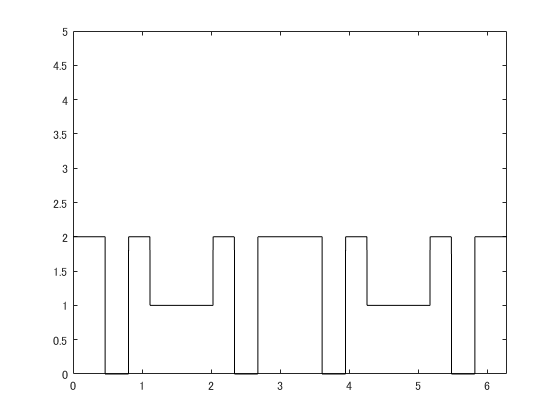

dc = 49; % 指間距離dcの設定
offset_theta = deg2rad(90);

n_array = double.empty(0,1);
theta =0:deg2rad(0.1):deg2rad(360);
for i = theta + (offset_theta)
    polygon_t = translate(polygon,[dc*cos(-i),dc*sin(-i)]);
    polyout = intersect(polygon,polygon_t);
    N = numboundaries(polyout);
    n_array = [n_array;N];
end

figure
plot(theta,n_array,'-k');
xlim([0 deg2rad(360)])
ylim([0 5])

nが変化するthetaを導出し，check_theta_arrayに格納

check_theta_array = double.empty(0,1);
for i = 2: size(theta,2)
    if n_array(i) ~= n_array(i-1)
        check_theta_array = [check_theta_array;theta(i)];
    end
end

nが変化するthetaの境界が結合境界か消失境界かを判定

del_theta = deg2rad(0.1);
check_boundary_array = char.empty(0,1);

for check_theta = check_theta_array'
    
    fg_value = 0;
    
    polygon1 = translate(polygon,[dc*cos(-check_theta+(offset_theta)),dc*sin(-check_theta+(offset_theta))]);
    polygon2_1 = translate(polygon,[dc*cos(-check_theta+(offset_theta)+del_theta),dc*sin(-check_theta+(offset_theta)+del_theta)]);
    polygon2_2 = translate(polygon,[dc*cos(-check_theta+(offset_theta)-del_theta),dc*sin(-check_theta+(offset_theta)-del_theta)]);
    
    polyout1 = intersect(polygon,polygon1);
    polyout2_1 = intersect(polygon,polygon2_1);
    polyout2_2 = intersect(polygon,polygon2_2);

    polyout1  = sortboundaries(polyout1,'centroid','ascend');
    polyout2_1  = sortboundaries(polyout2_1,'centroid','ascend');
    polyout2_2  = sortboundaries(polyout2_2,'centroid','ascend');

    polyout1_regions = Regions;
    polyout2_1_regions = Regions;
    polyout2_2_regions = Regions;
    
    for n = 1: numboundaries(polyout1)
        [x, y] = boundary(polyout1,n);

        poly_str = strcat('d_',sprintf('%02d',n));
        polyout1_regions.addprop(poly_str);
        polyout1_regions.(genvarname(['d_',sprintf('%02d',n)])) = polyshape(x,y);
    end

    for n = 1: numboundaries(polyout2_1)
        [x, y] = boundary(polyout2_1,n);

        poly_str = strcat('d_',sprintf('%02d',n));
        polyout2_1_regions.addprop(poly_str);
        polyout2_1_regions.(genvarname(['d_',sprintf('%02d',n)])) = polyshape(x,y);
    end

    for n = 1: numboundaries(polyout2_2)
        [x, y] = boundary(polyout2_2,n);

        poly_str = strcat('d_',sprintf('%02d',n));
        polyout2_2_regions.addprop(poly_str);
        polyout2_2_regions.(genvarname(['d_',sprintf('%02d',n)])) = polyshape(x,y);
    end
    
    for n = 1: numboundaries(polyout1)
        poly_union = intersect(polyout2_1, polyout1_regions.(genvarname(['d_',sprintf('%02d',n)])));
        if numboundaries(poly_union) == 0
            fg_value = 1;
        end
    end

    for n = 1: numboundaries(polyout2_1)
        poly_union = intersect(polyout1, polyout2_1_regions.(genvarname(['d_',sprintf('%02d',n)])));
        if numboundaries(poly_union) == 0
            fg_value = 1;
        end
    end
    
    for n = 1: numboundaries(polyout1)
        poly_union = intersect(polyout2_2, polyout1_regions.(genvarname(['d_',sprintf('%02d',n)])));
        if numboundaries(poly_union) == 0
            fg_value = 1;
        end
    end
    
    for n = 1: numboundaries(polyout2_2)
        poly_union = intersect(polyout1, polyout2_2_regions.(genvarname(['d_',sprintf('%02d',n)])));
        if numboundaries(poly_union) == 0
            fg_value = 1;
        end
    end
    
    if fg_value == 1
        check_boundary_array = [check_boundary_array;'v'];
    else
        check_boundary_array = [check_boundary_array;'b'];
    end
end

結合・離散境界を加えたnとthetaのグラフを

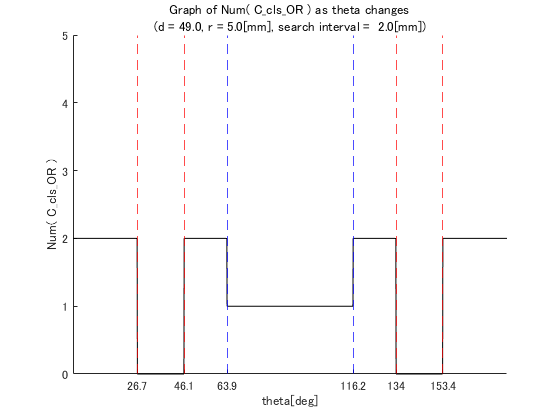

figure
hold on
plot(theta,n_array,'-k');
xlim([0 deg2rad(180)])

ylim([0 5])

for i = 1: size(check_theta_array,1)
    if check_boundary_array(i) == 'v'
        xline(check_theta_array(i),'--r');
    else
        xline(check_theta_array(i),'--b');
    end
end

title('Graph of Num( C\_cls\_OR ) as theta changes',sprintf( '(d = %0.1f, r = %0.1f[mm], search interval =  %0.1f[mm])' ,dc ,robot_r,dcc_search_interval))
xlabel('theta[deg]');
ylabel('Num( C\_cls\_OR )');
xticks(check_theta_array)
xticklabels(round(rad2deg(check_theta_array),1))
yticks([0 1 2 3 4 5])
yticklabels({'0','1','2','3','4','5'})

hold off